# Visualización Matriz de Confusión

Create vectors for the known groups and the predicted groups.

Ejemplo para dos clases.

g1= [3 2 2 ]';	% Known groups
g2 = [4 1 1]';	% Predicted groups

Return the confusion matrix.

C = confusionmat(g1,g2)

C =      0     0     0     0
     2     0     0     0
     0     0     0     1
     0     0     0     0


The indices of the rows and columns of the confusion matrix `C` are identical and arranged by default in the sorted order of `[g1;g2]`, that is, `(1,2,3,4)`.

The confusion matrix shows that the two data points known to be in group 1 are classified correctly. For group 2, one of the data points is misclassified into group 3. Also, one of the data points known to be in group 3 is misclassified into group 4. `confusionmat` treats the `NaN` value in the grouping variable `g2` as a missing value and does not include it in the rows and columns of `C`.

Plot the confusion matrix as a confusion matrix chart by using [`confusionchart`](docid:stats_ug.mw_b571feea-6af0-489f-b52c-a4b5141ac550). 

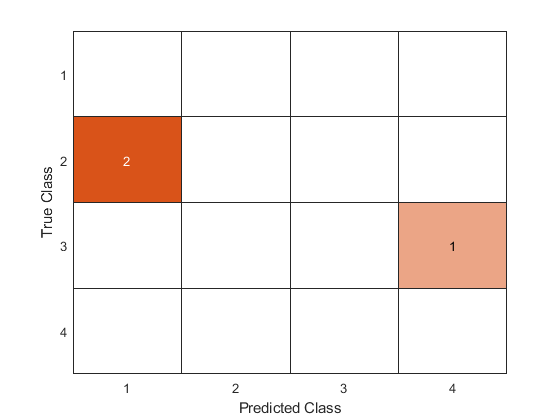

confusionchart(C)

You do not need to calculate the confusion matrix first and then plot it. Instead, plot a confusion matrix chart directly from the true and predicted labels by using [`confusionchart`](docid:stats_ug.mw_b571feea-6af0-489f-b52c-a4b5141ac550).

cm =   ConfusionMatrixChart with properties:

    NormalizedValues: [4×4 double]
         ClassLabels: [4×1 double]

  Show all properties


cm = confusionchart(g1,g2)

The `ConfusionMatrixChart` object stores the numeric confusion matrix in the `NormalizedValues` property and the classes in the `ClassLabels` property. Display these properties using dot notation.

cm.NormalizedValues

ans =      0     0     0     0
     2     0     0     0
     0     0     0     1
     0     0     0     0


cm.ClassLabels

ans =      1
     2
     3
     4


*Copyright 2012 The MathWorks, Inc.*